# Does the normalized signal variance result still hold when the number of neurons is held constant?

Find the association between the normalized signal variance for subsets of neurons of size 200 and the asymptotic ratio.

**Note: **Only run this cell if the variable org was not already created.

org = Org; org.init;

Calculating the normalized signal variance (NSV) on the subsets of size 200, with 100 random repetitions (with replacement).

figure;
org.correlogram('fixed_nsv', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations fixed_nsv vs. asymp_ratio: adj. R^2 = 0.488
Pearson: 0.738, p = 1.483309e-02, *
Spearman: 0.636, p = 5.444507e-02, n.s.
Kendall: 0.556, p = 2.860946e-02, *


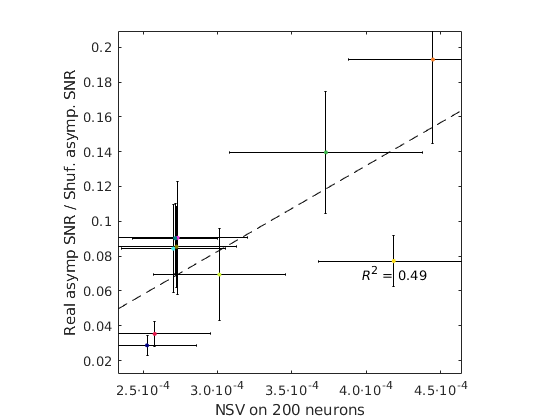

Utils.fix_exponent(gca, 'x', 1);
xlabel 'NSV on 200 neurons'
ylabel 'Real asymp SNR / Shuf. asymp. SNR'
axis square
Utils.printto('events_figs/f5_supplements', 'fixed_nsv_by_mouse.pdf');

figure;
org.correlogram('fixed_nsv', 'asymp_ratio', false, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Sessionwise correlations fixed_nsv vs. asymp_ratio: adj. R^2 = 0.210
Pearson: 0.470, p = 3.113789e-05, ***
Spearman: 0.467, p = 4.371317e-05, ***
Kendall: 0.321, p = 6.852168e-05, ***


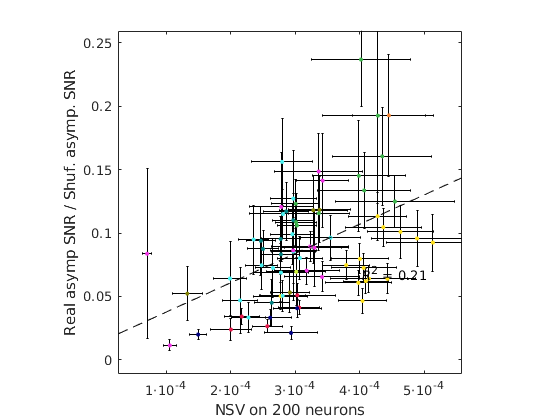

Utils.fix_exponent(gca, 'x', 0);
xlabel 'NSV on 200 neurons'
ylabel 'Real asymp SNR / Shuf. asymp. SNR'
axis square
Utils.printto('events_figs/f5_supplements', 'fixed_nsv_by_sess.pdf');

## Normalized signal variance for head direction and the asymptotic ratio

figure; org.correlogram('hd_nsv_fixed', 'hd_asymp_ratio', true, true, true);

Using only 34 out of 110 sessions
Mouse-aggregated correlations hd_nsv_fixed vs. hd_asymp_ratio: adj. R^2 = 0.251
Pearson: 0.598, p = 1.172345e-01, n.s.
Spearman: 0.381, p = 3.598710e-01, n.s.
Kendall: 0.286, p = 3.987599e-01, n.s.


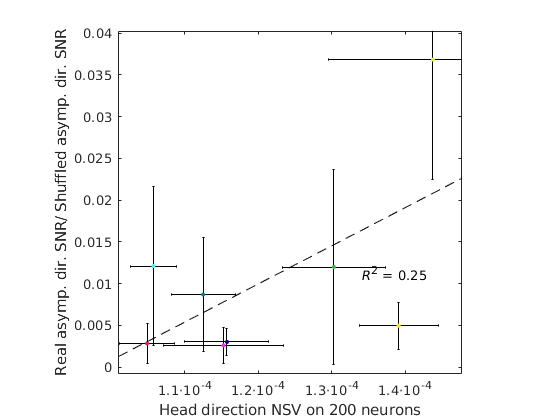

xlabel 'Head direction NSV on 200 neurons'
ylabel 'Real asymp. dir. SNR/ Shuffled asymp. dir. SNR'
Utils.fix_exponent(gca, 'x', 1);
axis square
Utils.printto('events_figs/f5_supplements', 'HD_fixed_nsv_by_mouse.pdf');

figure; org.correlogram('hd_nsv_fixed', 'hd_asymp_ratio', false, true, true);

Using only 34 out of 110 sessions
Sessionwise correlations hd_nsv_fixed vs. hd_asymp_ratio: adj. R^2 = 0.012
Pearson: 0.205, p = 2.436543e-01, n.s.
Spearman: 0.279, p = 1.095078e-01, n.s.
Kendall: 0.205, p = 9.113800e-02, n.s.


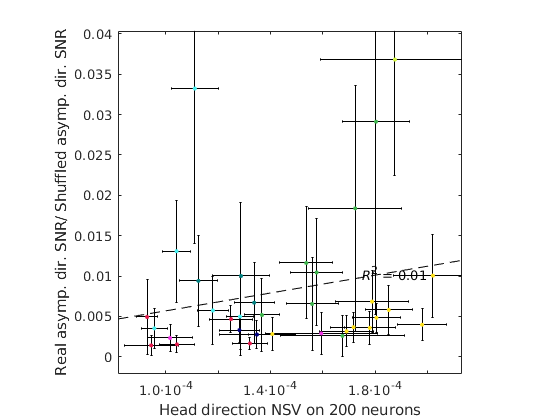

xlabel 'Head direction NSV on 200 neurons'
ylabel 'Real asymp. dir. SNR/ Shuffled asymp. dir. SNR'
Utils.fix_exponent(gca, 'x', 1);
axis square
Utils.printto('events_figs/f5_supplements', 'HD_fixed_nsv_by_sess.pdf');

Using only 34 out of 110 sessions
Sessionwise correlations hd_svn vs. hd_asymp_ratio: adj. R^2 = 0.365
Pearson: 0.620, p = 9.322308e-05, ***
Spearman: 0.686, p = 1.320817e-05, ***
Kendall: 0.519, p = 6.527858e-06, ***


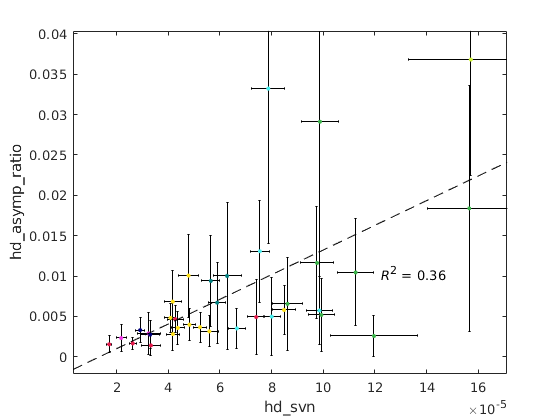

figure; org.correlogram('hd_svn', 'hd_asymp_ratio', false, true, true);

Using only 34 out of 110 sessions
Sessionwise correlations num_neurons vs. hd_asymp_ratio: adj. R^2 = 0.216
Pearson: -0.490, p = 3.277460e-03, **
Spearman: -0.595, p = 2.039154e-04, ***
Kendall: -0.437, p = 3.129706e-04, ***


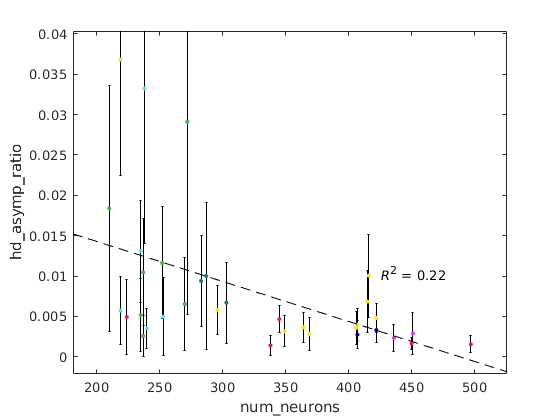

figure; org.correlogram('num_neurons', 'hd_asymp_ratio', false, true, true);

Using only 73 out of 110 sessions
Sessionwise correlations num_neurons vs. hd_svn: adj. R^2 = 0.577
Pearson: -0.764, p = 4.018004e-15, ***
Spearman: -0.816, p = 1.541133e-18, ***
Kendall: -0.651, p = 4.595122e-16, ***


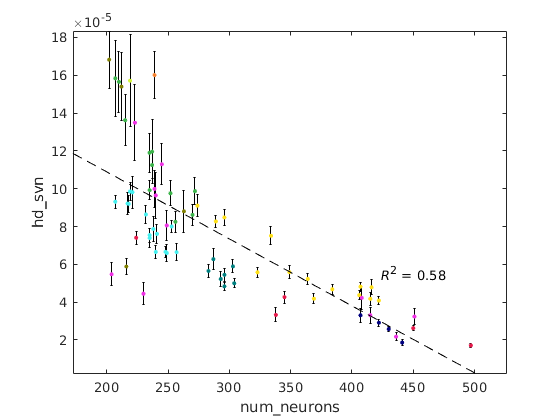

figure; org.correlogram('num_neurons', 'hd_svn', false, true, true);

T = org.sess_prop;
Tc = org.sess_prop_conf;
T = T(T.num_neurons > 200 & Tc.hd_asymp_ratio < T.hd_asymp_ratio & Tc.hd_svn < T.hd_svn, :);
fitlm(T, 'hd_asymp_ratio ~ hd_svn + num_neurons')

ans = Linear regression model:
    hd_asymp_ratio ~ 1 + num_neurons + hd_svn

Estimated Coefficients:
                    Estimate         SE         tStat       pValue 
                   __________    __________    ________    ________

    (Intercept)    -0.0071909      0.012442    -0.57796     0.56747
    num_neurons    1.1157e-05    2.6403e-05     0.42256     0.67553
    hd_svn              175.7        64.305      2.7322    0.010292


Number of observations: 34, Error degrees of freedom: 31
Root Mean Squared Error: 0.00707
R-squared: 0.387,  Adjusted R-Squared: 0.348
F-statistic vs. constant model: 9.8, p-value = 0.000502

T = org.sess_prop;
Tc = org.sess_prop_conf;
T = T(T.num_neurons > 200 & Tc.asymp_ratio < T.asymp_ratio & Tc.signal_var_norm < T.signal_var_norm, :);
fitlm(T, 'asymp_ratio ~ signal_var_norm + num_neurons')

ans = Linear regression model:
    asymp_ratio ~ 1 + num_neurons + signal_var_norm

Estimated Coefficients:
                        Estimate         SE          tStat        pValue  
                       __________    __________    _________    __________

    (Intercept)        0.00021577      0.028626    0.0075377       0.99401
    num_neurons        4.9336e-05    6.5407e-05      0.75429       0.45324
    signal_var_norm        411.31        60.694       6.7768    3.3681e-09


Number of observations: 72, Error degrees of freedom: 69
Root Mean Squared Error: 0.0285
R-squared: 0.575,  Adjusted R-Squared: 0.563
F-statistic vs. constant model: 46.7, p-value = 1.47e-13